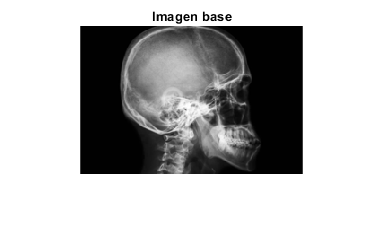

%% Mathematical Morphology
% Carlos Enrique López Jimenez A01283855
% Genaro Gallardo Bórquez A01382459
% Claudia Esmeralda González Castillo A01411506
% Jesus Eduardo Martinez Herrera A01283785
% Juan Diego García Manrique A00829257
% Mario Veccio Castro Berrones A00826824

% Se aumento en valor de 3 todos los tamanos de los discos

% Se lee la imagen
f=imread('craneo.jpg');
f=double(f(:,:,1));
f=f/max(max(f));
% Se escala el tamano de la imagen
f=imresize(f,0.25);
% Se muestra la primera figura
figure(1)
imshow(f,[]), title('Imagen base')

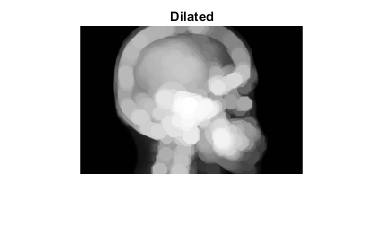


%% Dilatation

% Crea una superficie con forma de disco
se = strel('disk',8);

% Dilata la figura utilizando la estructura SE
BW2 = imdilate(f,se);
figure(2)
imshow(BW2), title('Dilated')

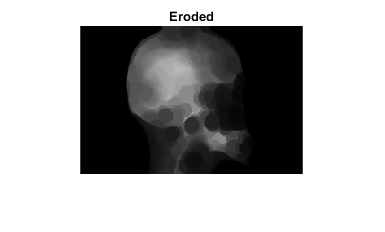

%% Erosion

se = strel('disk',8);
% Erosiona la figura utilizando la estructura SE
BW3 = imerode(f,se);
imshow(BW3), title('Eroded')

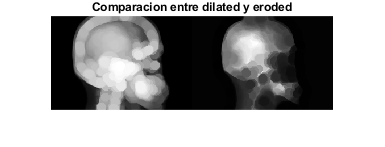

figure(3)
imshowpair(BW2,BW3,'montage')
title('Comparacion entre dilated y eroded')

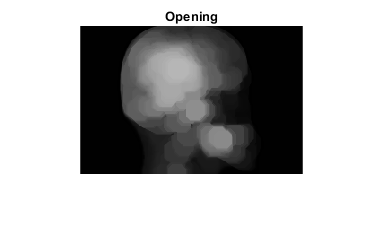

%% Opening

se = strel('disk',10);
% Apertura morfologica, primero se dilata y despues se erosiona usando la
% misma estructura
BW2 = imopen(f,se);
figure(4)
imshow(BW2), title('Opening')

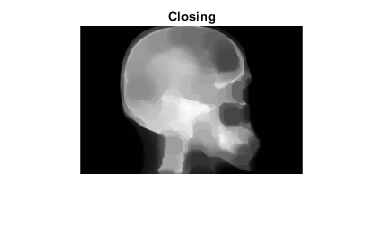

%% Closing

se = strel('disk',10);
% Primero se erosiona y despues se dilata usando la estructura SE
BW2 = imclose(f,se);
figure(5)
imshow(BW2), title('Closing')

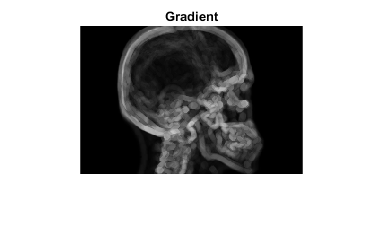

%% Gradient

se = strel('disk',4);
BW1 = imdilate(f,se) - imerode(f,se);
figure(6)
imshow(BW1), title('Gradient')

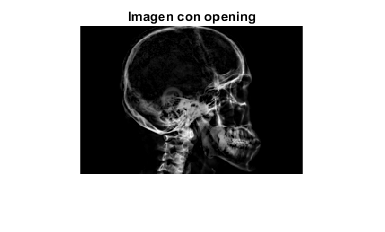


%% Lets play with the x-ray

se = strel('disk',10);
BW3 = f-imopen(f,se);
figure(17)
imshow(BW3,[]), title('Imagen con opening')

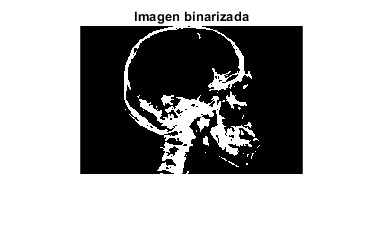

bw = imbinarize(BW3);
figure(18)
imshow(bw,[]), title('Imagen binarizada')

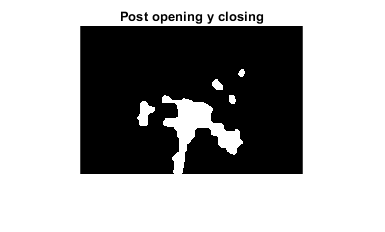

bw = imopen(bw,strel('disk',4));
bw = imclose(bw,strel('disk',7));
figure(19)
imshow(bw,[]), title('Post opening y closing')

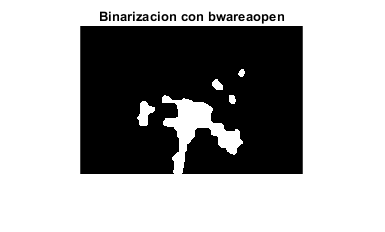

bw = bwareaopen(bw,50);
figure(20)
imshow(bw,[]), title('Binarizacion con bwareaopen')

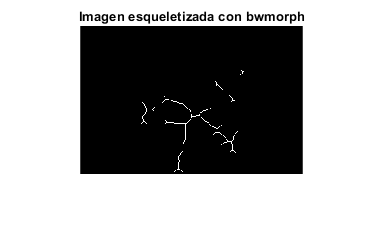

BW3 = bwmorph(bw,'skel',Inf);
figure(21)
imshow(BW3), title('Imagen esqueletizada con bwmorph')

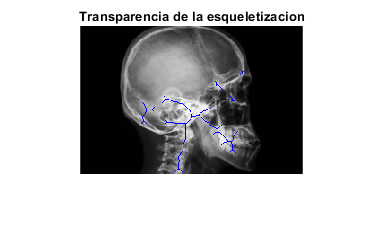

figure(22)
imshow(labeloverlay(f,BW3,'Transparency',0)), title('Transparencia de la esqueletizacion')